clear;clc;close all

layerfolder='../Tool_landscape/data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 5.710139 seconds.


Elapsed time is 23.969184 seconds.


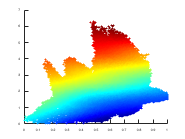

Elapsed time is 24.821716 seconds.


InfoInitialPoint = InitialPoint(Dimensions,'harmonic');

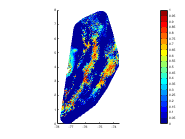

Elapsed time is 0.575511 seconds.


MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 50, -3, true, 'GenSP', true, true);

----Finding clusters----
1 clusters identified


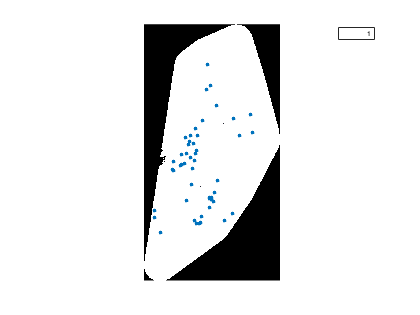

Elapsed time is 4.472592 seconds.
----Finding correlation----
Elapsed time is 6.639229 seconds.
----Creating predictors----
¡All done!
Elapsed time is 7.612634 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false);

data{1}.T2

ans = 498×22 table
    Name      LONG        LAT      bio1    bio2    bio3    bio4    bio5    bio6    bio7    bio8    bio9    bio10    bio11    bio12    bio13    bio14    bio15    bio16    bio17    bio18    bio19
    _____    _______    _______    ____    ____    ____    ____    ____    ____    ____    ____    ____    _____    _____    _____    _____  

----Modeling----


ij = 1

-Model 1


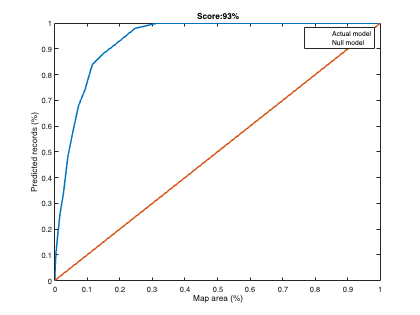

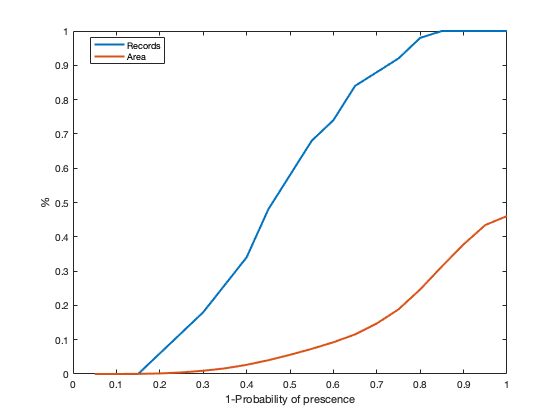

Elapsed time is 1.785481 seconds.


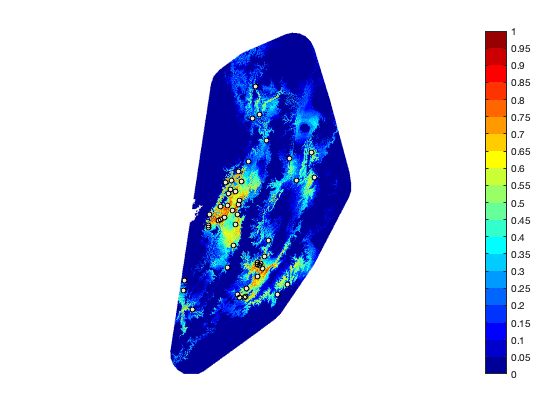

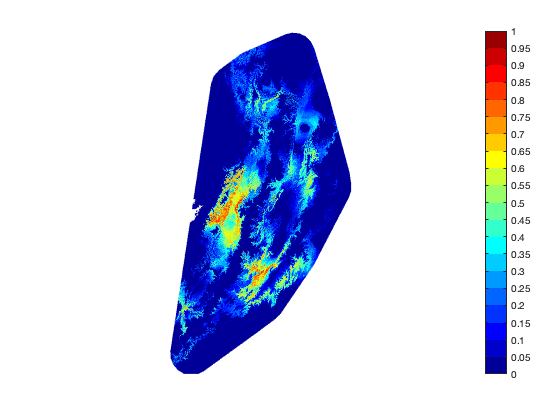

dataf = bnm_modeling(data, '', true, 4, false);

%close all
%show=true;%show graphics
%outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
%outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
%data = bnm_modeling2(data{1},show,outlier,outlier2)